# Test Mappings - Velocity

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
% Define dimension of modes
SSMDim = 6; hSSMDim = SSMDim/2;
load obsDecayDataC

## Visualize Training Data

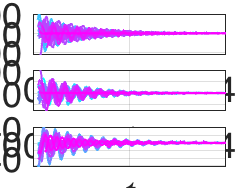

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

ofData = oData;
Ts = 1/(ofData{iTraj,1}(2)-ofData{iTraj,1}(1));
cutFreqHz = 15;
for iTraj = 1:size(oData, 1)
    ofData{iTraj,2} = transpose(lowpass(transpose(oData{iTraj,2}), cutFreqHz, Ts));
end

Visualize filtered data

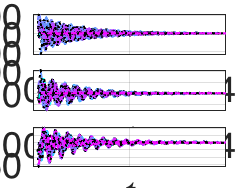

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
        plot(ofData{iTraj,1},ofData{iTraj,2}(trajs(iObs),:), 'k:', 'Linewidth',1)
    end
end

Run SVD, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 95% of variance is explained by the first three PCA modes.

disp('PCA')

PCA


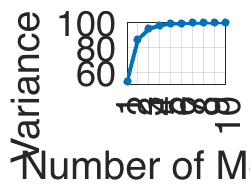

% Perform SVD on displacement field
[V,S,~] = svd(cat(2,ofData{:,2}), 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])

% Generate transformation to get velocities in the reduced order
% coordinates
outdofs = [1 2 3];
yData = ofData;
for iTraj = 1:size(yData,1)
    yData{iTraj,1} = yData{iTraj,1}(2:end);
    yData{iTraj,2} = [yData{iTraj,2}(:,1:end-1); yData{iTraj,2}(:,2:end)];
end
Dt = yData{1,1}(2)-yData{1,1}(1);
sliceInt = [0, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);
Uproj = transpose(V(:,1:SSMDim/2));
Vde = transpose([Uproj zeros(size(Uproj)); zeros(size(Uproj)) Uproj]);


% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
indTest = [5 15 21 32 38];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

%% Trajectory lifting requires reduced coordinates (ensures y is on manifold, 
% hence yRec =/= yDataTrunc)
disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 1.9705

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 1.6204

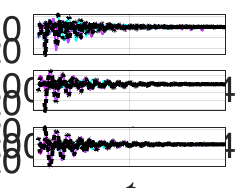


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

% Obtain derivatives
etaMechDataTrunc = etaDataTrunc; rdofs = SSMDim /2; Dt = etaDataTrunc{1,1}(2)-etaDataTrunc{1,1}(1);
DiffMat = [zeros(rdofs) eye(rdofs); eye(rdofs)/Dt -eye(rdofs)/Dt];
for iTraj = 1:size(etaDataTrunc)
    etaMechDataTrunc{iTraj,2}=DiffMat*etaDataTrunc{iTraj,2};
end

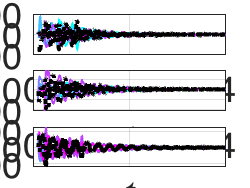

% Check derivatives
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$\dot{\eta}_1$", "$\dot{\eta}_2$", "$\dot{\eta}_3$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(etaMechDataTrunc{indTest(iTraj),1},etaMechDataTrunc{indTest(iTraj),2}(outdofs(iObs)+SSMDim/2,:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    [dX_idt,X_i,t_i] = finiteTimeDifference(etaMechDataTrunc{indTest(iTraj),2}(1:3,:),etaMechDataTrunc{indTest(iTraj),1},1);
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(t_i,dX_idt(iObs,:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsMech(etaMechDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =  -25.6642 + 0.1934i
  27.7378 + 0.0000i
  26.6164 + 0.0000i


Rauton = RDInfo.reducedDynamics.map

Rauton = function_handle with value:
    @(x)W_r*phi(x)

Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = Inf

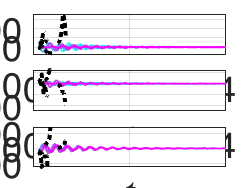


customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(etaMechDataTrunc{indTest(iTraj),1},etaMechDataTrunc{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(etaRec{indTest(iTraj),1},etaRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Load controlled data

% Load and process tpwl data for tip coords only
load tpwl_data
%load koopman_data_figureEight
y = y(13:end, :); % only tip displacements

zu = {};
%keptIdxs = 100:600;
keptIdxs = 1:size(y,2);
zu{1,1} = t(keptIdxs); zu{1,2} = y(:, keptIdxs) - y(:, end); uCell{1,1} = t(keptIdxs); uCell{1,2} = u(:, keptIdxs);
[yDataInput, Yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


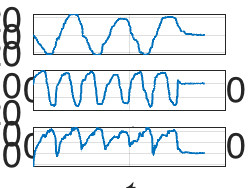


% v then w mapping
yDataRemapped = yDataInput;
xData = yDataInput;
for iTraj = 1:size(yDataInput, 1)
    xData{iTraj, 2} = transpose(Vde) * yDataInput{iTraj, 2}; % Project down
    yDataRemapped = liftTrajectories(IMInfo, xData); % Project up
    % yDataRemapped{iTraj, 2} = Vde * xData{iTraj, 2}; % Project up with standard projection
end

% Plot data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(zu{iTraj,1},zu{iTraj,2}(iObs,:),'Linewidth',1)
    end
end

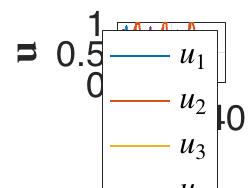

% Plot control inputs
customFigure;
plot(uCell{1,1}, uCell{1,2},'Linewidth',1);
xlabel('$t$','Interpreter','latex');
ylabel('$\mathbf{u}$','Interpreter','latex');
legend('$u_1$','$u_2$','$u_3$','$u_4$','location','NE','Interpreter','latex');

## Learn control matrix

From theory, we expect the following corrections in the reduced order model:


$$\dot{\mathit{\mathbf{x}}} =\mathit{\mathbf{r}}\left(\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{B}}}_{\mathit{\mathbf{r}}} \mathit{\mathbf{u}}\left(t\right)$$



$$\mathit{\mathbf{y}}=\mathit{\mathbf{v}}\left(\mathit{\mathbf{x}}\right)+{\mathit{\mathbf{B}}}_{\mathit{\mathbf{v}}} \int_0^t \mathit{\mathbf{u}}\left(s\right)\textrm{ds}$$


under the assumptions that the control action is small and that the dynamics of other structural modes can be neglected.

% Setup trajectories for fit
[Yu, yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


[Udelay, ~] = coordinatesEmbeddingControl(uCell, SSMDim, 'OverEmbedding', overEmbed, 'ndim', size([zu{1,2}], 1));

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


uembedDim = size(Udelay{1,2},1);
udofs = [uembedDim-3, uembedDim-2 uembedDim-1 uembedDim];

yuxData = cell(size(Yu,1),4);
for iTraj = 1:size(Yu, 1)
   yuxData{iTraj,1} = Yu{iTraj,1};
   yuxData{iTraj,2} = Yu{iTraj,2};
   yuxData{iTraj,3} = Udelay{iTraj,2}(udofs,:);
   yuxData{iTraj,4} = IMInfo.chart.map(Yu{iTraj,2});
end
% Fit control matrices
[Br,Bv,regErrors] = fitControlMatrices(yuxData,RDInfo,IMInfo)

Br = 	1.0e+04 *

   -0.0011    0.0003   -0.0035    0.0023
   -0.0034    0.0073   -0.0224    0.0100
   -0.0028    0.0006   -0.0024    0.0009
   -1.0069   -1.7535   -0.3184    3.0446
   -3.4055    2.8549   -3.2448    2.1095
   -1.5472   -0.7618   -0.3723   -0.5674


Bv =     3.9284    3.6262   13.6033  -19.7914
  -16.2322    1.4028   29.5707   -0.4617
   -9.5425   -8.5060   54.4597  -13.4951
    4.8505   -1.0604   11.0881  -17.5864
  -11.4444   -7.1631   47.5784  -12.4949
   -8.0202    2.8732  -25.2712   29.4205
   -0.4990    8.4467    5.7832  -17.0087
   -0.9579  -13.6105   48.3907  -19.6651
    1.6775   21.2240  -80.2310   31.8839
   -8.4306   13.3306   -7.7804    0.4697


regErrors =    27.2679   10.1642


% Update models
Rauton = RDInfo.reducedDynamics.map;
R = @(t,x,u) Rauton(x) + Br*u;
Vauton = IMInfo.parametrization.map;
V = @(x,u_int) Vauton(x) + Bv*u_int;

**Validate Control model**

%load koopman_data_figureEight
% load koopman_data
zu{1,1} = t; zu{1,2} = y - y(:, end); uCell{1,1} = t; uCell{1,2} = u;
[Yu, yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


[Udelay, ~] = coordinatesEmbeddingControl(uCell, SSMDim, 'OverEmbedding', overEmbed, 'ndim', size([zu{1,2}], 1));

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.



yuxData = cell(size(Yu,1),4);
for iTraj = 1:size(Yu, 1)
   yuxData{iTraj,1} = Yu{iTraj,1};
   yuxData{iTraj,2} = Yu{iTraj,2};
   yuxData{iTraj,3} = Udelay{iTraj,2}(udofs,:);
   yuxData{iTraj,4} = IMInfo.chart.map(Yu{iTraj,2});
end

iTraj = 1;
ti = yuxData{iTraj,1};
yi = yuxData{iTraj,2};
ui = yuxData{iTraj,3};
xi = yuxData{iTraj,4};
uiInt = integrateTimeSeries(ui,ti(2)-ti(1));



Check geometry

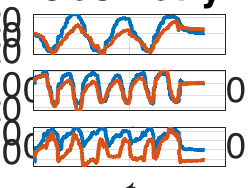

yiRec = V(xi,uiInt);
zi = yi(outdofs,:); ziRec = yiRec(outdofs,:); 

% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title ('Geometry')
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(ti, zi(iObs, :),'Linewidth',2);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(ti, ziRec(iObs, :),'Linewidth',2);
end

Check dynamics

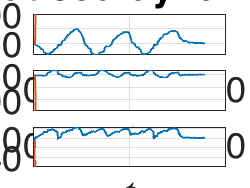


uFun = @(t) transpose(interp1(ti, transpose(ui), t));
[tiPred,xiPred] = ode45(@(t,x) R(t,x,uFun(t)),ti,xi(:,1)); 
tiPred = transpose(tiPred); xiPred = transpose(xiPred); 

% Plot time series
customFigure('subPlot',[3 1]);
labelsRD = {'$x_1$', '$x_2$', '$x_3$'};
subplot(3,1,1); title ('Reduced dynamics')
for iPlt = 1:3
    subplot(3,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labelsRD(iPlt),'Interpreter','latex');
end
for iObs = 1:3
    subplot(3,1,iObs);
    plot(ti, xi(iObs, :),'Linewidth',1);
end
for iObs = 1:3
    subplot(3,1,iObs);
    plot(tiPred, xiPred(iObs, :),'Linewidth',1);
end

Check overall reduced-order model

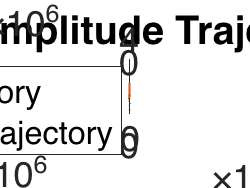

nStepsPred = length(tiPred);
if nStepsPred<length(ti)
   tiPred(nStepsPred+1:length(ti)) = NaN; xiPred(:,nStepsPred+1:length(ti)) = NaN; 
end
yiPred = V(xiPred,uiInt);
zi = yi(outdofs,:); ziPred = yiPred(outdofs,:);

% Visualize the trajectory in 3d
customFigure; 
plot3(zi(1, :), zi(2, :), zi(3, :),'Linewidth',1);
plot3(ziPred(1, :), ziPred(2, :), ziPred(3, :),'Linewidth',1);
legend('True Trajectory', 'Predicted Trajectory');
title('Big Amplitude Trajectory');
view(3);


RMSE = sum(sqrt(mean((ziPred(1:3, :) - zi).^2))) / size(ziPred, 2)

RMSE = NaN

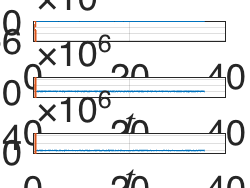


% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(ti, zi(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tiPred, ziPred(iObs, :),'Linewidth',1);
end

**Validate short time Control model**

%load koopman_data_figureEight

% Load and process tpwl data for tip coords only
load tpwl_data
y = y(13:end, :);
y_eq = y_eq(13:end);

Nhoriz = 3;
zTrue = y - y_eq';
tTrue = t;
uTrue = u;

[yData, ~] = coordinatesEmbeddingControl({tTrue, zTrue}, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


nEval = length(yData{1,1})-Nhoriz;
yDataPredHoriz = cell(1,5);

etaData = yData;
for iTraj=1:size(etaData, 1)
    etaData{iTraj,2} = transpose(Vde)*yData{iTraj,2};
end
iRow = 1;
for iTime = 1:nEval
    uHoriz = uTrue(:,iTime:iTime+Nhoriz);
    tHoriz = tTrue(iTime:iTime+Nhoriz);
    uFun = @(t) transpose(interp1(tHoriz, transpose(uHoriz), t));
    [iTimeRec, ietaRec] = ode15s(@(t,x) R(t,x,uFun(t)),tHoriz,etaData{1,2}(:,iTime));
    % Lift
    iyRec = liftTrajectories(IMInfo, {iTimeRec, transpose(ietaRec)});
    
    yDataPredHoriz{iRow,1} = etaData{iTraj,1}(iTime:iTime+Nhoriz);
    yDataPredHoriz{iRow,2} = ietaRec(:,:);
    yDataPredHoriz{iRow,3} = etaData{iTraj,1}(iTime+Nhoriz);
    yDataPredHoriz{iRow,4} = iyRec{1,2}(outdofs,:);
    yDataPredHoriz{iRow,5} = iTime;
    iRow = iRow + 1;
end

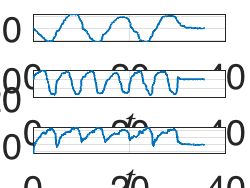

Error using plot
Vectors must be the same length.

% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zTrue(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    for iTraj=1:size(yDataPredHoriz,1)
        plot(yDataPredHoriz{iTraj,1}, yDataPredHoriz{iTraj,4}(iObs,:),'Linewidth',1);
    end
end